clear

%% parameters for running batch script
% parameters for loading data
task      = 'aur';
beapp_tag = '_updated_trials_updated_trigger_notch_erpfilt_noblcorr';
data_path = fullfile( 'Z:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );
file_tag = [beapp_tag '_2022-12-12_yb_.1-30_seg_run_in_beapp_100msbl_corr_2'];
file_tag = [beapp_tag '_2022-09-01_gp']

file_tag = '_updated_trials_updated_trigger_notch_erpfilt_noblcorr_2022-09-01_gp'

file_tag = ['_HAPPE_V3_2023-01-19_yb_noexclusion_200msbl'];
file_tag = ['_HAPPE_V3_2023-01-20_yb_noexclusion_full_200ms_individ_bl'];
file_tag = [beapp_tag, '_2023-02-13_yb_50ms']

file_tag = '_updated_trials_updated_trigger_notch_erpfilt_noblcorr_2023-02-13_yb_50ms'

% parameters for processing
method    = 'trials_avg';
rois      = {'C3'};
groups    = {'TD','ASD'};
%erps      = {'N13','P25','P50','N80','P100','N140','P300','P4','P190','N300';  % components to calculate/plot
exclude   = {};
erps = {'N13','P25', 'P50', 'N80', 'P100','N140','P300','P4' ,'P190','N300','N13_P25_dist','P25_P50_dist','P50_N80_dist','N80_P100_dist','P100_N140_dist','N140_P300_dist','P300_P4_dist'};
% parameters for plots
rescale   = false;
save_figs = true;
cond_names = {'1_mN'	,'2_mN',	'5_mN',	'10_mN',	'20_mN'	,'40_mN'	,'50_mN'	,'75_mN',	'100_mN'};
cond_names = {'2mN','5mN','10mN','20mN','40mN','50mN','75mN'}

cond_names = 1×7 cell array
    {'2mN'}    {'5mN'}    {'10mN'}    {'20mN'}    {'40mN'}    {'50mN'}    {'75mN'}


colors    = {'#4444c9','#32a852','#db4214'};
colors = {'red','green','blue','yellow'};
params = {'CL EEG','CL ERP','N EEG','N ERP'};
% colors    = {'#000','#444','#888','#ccc'};
 x_label   = 'Intentisity (mN)';
%x_label   = 'Condition';
y_label   = 'ERP';
%xlims     = [1 5];

%% load batch information
%task_path = get_task_path(task);
% save_path = 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\Aurora_20ms','erp';
% task_path_batch =fullfile('Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\Aurora_20ms','erp',['erp' file_tag '.mat']);
% task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\erp\erp_3_14_23_notch_filt_50msbl_2023-03-15_yb_50ms.mat';
% task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\erp\erp_3_14_23_notch_filt_100msbl_2023-03-15_yb_noblcorr.mat';
% task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\erp\erp_3_16_23_notch_filt_100msbl_jointprob_meandet_2023-03-16_yb_100msblcorr_meandet_all'
% 
% load(task_path_batch,'batch','data');
batch.method  = method;
batch.rescale = rescale;

% calculate or load group averages
%[data,batch] = calculate_erp_grp_avgs(batch,exclude);

## Step 1: Bin Data by Length

segment_path =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\segment_3_16_23_notch_filt_100msbl_jointprob_notrialalign';
seg_dir = dir(fullfile(segment_path,'*.mat*'))

seg_dir = 2×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


addpath(segment_path)
for file = 1:length(seg_dir)
    fname = seg_dir(file).name;
    load(fname)
    file_proc_trimmed = find(ismember({file_proc_info.evt_info{1,1}(:).type},'Non_Target'));
    file_proc_trimmed_final = {file_proc_info.evt_info{1,1}(setdiff([1:length(file_proc_info.evt_info{1,1})],file_proc_trimmed))};
    for i_c = 1:size(file_proc_info.evt_conditions_being_analyzed,1)
    curr_cond_force_length = {file_proc_trimmed_final{1,1}(file_proc_info.(strcat('segs_to_keep',num2str(i_c)))).behav_code};
% check and fill in NaN values
nan_idxs= find(cell2mat(cellfun(@(x) any(isnan(x)),curr_cond_force_length,'UniformOutput',false)));
   if length(nan_idxs)>=1 
curr_cond_force_length{nan_idxs} = '999-999';
   end
    curr_cond_split_force_length = cellfun(@(x) (strsplit(x,'-')),curr_cond_force_length,'UniformOutput',false);
    true_force{file,i_c} = cell2mat(cellfun(@(x) (str2num(char(x(1)))),curr_cond_split_force_length,'UniformOutput',false));
    true_length{file,i_c} = cell2mat(cellfun(@(x) (str2num(char(x(2)))),curr_cond_split_force_length,'UniformOutput',false));
    clear curr_cond_force_length curr_cond_split_force_length


    % build eeg_data based on length histogram
    [~,edges,bin] = histcounts(true_length{file,i_c},4);
    all_bin_idxs{file,i_c}=bin;
    all_edges{file,i_c}=edges;
    for bin_i = 1:4
    binned_eeg.(strcat('bin_',num2str(bin_i))).(strcat('cond_',num2str(i_c))).(fname(1:5))=eeg_w{i_c,1}(:,:,(all_bin_idxs{file,i_c}==bin_i));
    end
    end
    clear file_proc_info eeg_w
end

Unrecognized field name "type".

## Feed those into calculate ERPS

for i_c = 1:7

    for bin_i = 1:4
        batch_tag = strcat('bin_',num2str(bin_i),'cond_',num2str(i_c));
    %prep eeg
    curr_cond_bin = binned_eeg.(strcat('bin_',num2str(bin_i))).(strcat('cond_',num2str(i_c)));
    files = fields(curr_cond_bin);

    for i_f = 1:length(files)
    eeg_dir(i_f).name = files{i_f};
    eeg_dir(i_f).data = {curr_cond_bin.(files{i_f})};
    end
    % run batch erp

   batch_path =  batch_erp_calculate_function_yb('study','Aurora',batch_tag,'3_16_23_notch_filt_100msbl_jointprob_notrialalign','pc','trials',eeg_dir);
   %load(batch_path,'data','ids','batch');
   batch_paths.(strcat('bin_',num2str(bin_i))).(strcat('cond_',num2str(i_c))) = batch_path;
%    method_name = get_method_plot_name(method);
% 
%    all_data.(strcat('bin_',num2str(bin_i))).(strcat('cond_',num2str(i_c))) = data;
%    all_batch.(strcat('bin_',num2str(bin_i))).(strcat('cond_',num2str(i_c))) = batch;
%    all_ids.(strcat('bin_',num2str(bin_i))).(strcat('cond_',num2str(i_c)))=ids;
   clear data ids batch batch_tag

    end
end

Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs for participant p108
Finished.
Calculating ERPs for participant p107
Calculating ERPs

%load back that batch
%append to larger data and batch struct


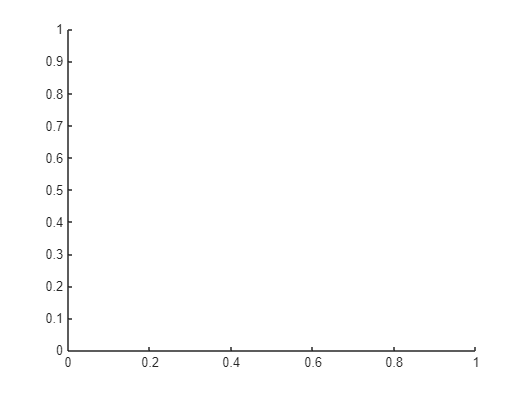

Error using scatter (line 61)
X and Y must be vectors of the same length, matrices of the same size, or a combination of a vector and a matrix where the length of the vector matches either
the number of rows or columns of the matrix.

method_name = get_method_plot_name(method);

% iterate through group
n_grps = length(groups);
n_rois = length(rois);
n_erps = length(erps);
for i_r = 1:n_rois
    roi = rois{i_r};
    for i_e = 1:n_erps
f= figure(); hold on
        for i_c = 1:7
            subplot_mat = [1 2 3 4;
                5 6 7 8]; % conditions by bins
            subplot_mat = [1 2];

            for bin_i = 1:4
                    load(batch_paths.(strcat('bin_',num2str(bin_i))).(strcat('cond_',num2str(i_c))))
                % pull data
                curr_data = data; %all_data.(strcat('bin_',num2str(bin_i))).(strcat('cond_',num2str(i_c)));
                % initialize variables
                grp_avg = []; grp_err = []; grp_labels = cell(1,n_grps); grp_si = [];

                % skip if ERP component not in ROI
                erp = erps{i_e};
                if ~isfield(curr_data.(roi),erp)
                    continue
                end
                % get group data
                %         for i_g = 1:n_grps
                %             % get group data
                %             group = groups{i_g};
                %             avg = data.(group).(roi).(erp).avg; err = data.(group).(roi).(erp).err;
                %             grp_avg = [grp_avg; avg];
                %             grp_err = [grp_err; err];
                %             grp_labels{i_g} = [group ', n=' int2str(batch.groups.(group).N)];
                %
                %             % calculate suppression index for TSS
                %             if contains(task,'tss')
                %                 grp_si = [grp_si; 1 - avg(3)/(avg(1)+avg(2))];
                %             end
                %         end
                p_ids =unique(cellfun(@(x) x(1:5),fields(curr_data.(roi).(erp)),'UniformOutput',false));
                % generate plots
                for i_p = 1:length(p_ids)
                    curr_file_edges = all_edges{i_p,i_c};
                    curr_bin_idxs = all_bin_idxs{i_p,i_c};
                    curr_force = true_force{i_p,i_c};
                    x_axis = curr_force(find(curr_bin_idxs == bin_i));
                    x_axis = x_axis*50;
                    str = strcat('Bin Edges:',num2str(curr_file_edges(bin_i)),'to',num2str(curr_file_edges(bin_i+1)));
                    if strcmp(p_ids{i_p},'pAuro'); continue; end
                    subplot(2,1,subplot_mat(i_p))
                                f = figure; hold on
            f = figure; hold on
            try
scatter(x_axis,curr_data.(roi).(erp).(strcat(p_ids{i_p},'_',method)),'DisplayName',str)
            catch
                disp('couldnt plot')
                continue
            end
                    hold on
                   % annotation('textbox',[0.15 0.6 0.3 0.3],'String',str,'FitBoxToText','on'); 
                   % errorbar(curr_data.(roi).(erp).(strcat(p_ids{i_p},'_',method)),[repmat(.001,1,7)],'-o','LineWidth',2,'Color',colors{i_p})
                fig_title = [p_ids{i_p}, ' ',roi, ' ' ,erp ,' ' ,method_name];
                %if batch.rescale
               %     fig_title = [fig_title ', rescaled'];
               % end
                title(fig_title)
                xlabel(x_label), ylabel(y_label)
                
                end
                %legend(p_ids)
                
                %xticks(1:5)
                xticklabels(cond_names)
                %ylim([-6.5 -0.5])
                % save figure
                if 0
                    plot_fname = strrep([task '_' fig_title],' ','_');
                    fig_path = fullfile(batch.path_task_figs,[plot_fname beapp_tag '.jpg']);
                    if ~exist(batch.path_task_figs,'dir')
                        mkdir(batch.path_task_figs);
                    end
                    saveas(f,fig_path)
                end
                clear data ids batch
            end
        end

    end
end